# Use Custom `trackingKF` with Control Inputs

Specify a simulation time of 10 seconds with a time step of 1 second.

rng(2021) % For repeatable results
simulationTime = 20;
dt = 1;
tspan = 0:dt:simulationTime;
steps = length(tspan);

Specify the motion model as a 2-D constant velocity model with a state of [`x`; `vx`; `y`; `vy`]. The measurement is [`x`; `y`]. 

A1D = [1 dt; 0 1]; 
A = kron(eye(2),A1D) % State transiton model

A =      1     1     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1


H1D = [1 0];
H = kron(eye(2),H1D) % Measurement model 

H =      1     0     0     0
     0     0     1     0


sigma = 0.2;
R = sigma^2*eye(2) % Measurement noise covariance

R =     0.0400         0
         0    0.0400


Specify a control model matrix. 

B1D = [0; 1];
B = kron(eye(2),B1D) % Control model matrix

B =      0     0
     1     0
     0     0
     0     1


Assume the control inputs are sinusoidal on the velocity components, `vx` and `vy`. 

gain = 5;
Ux = gain*sin(tspan(2:end));
Uy = gain*cos(tspan(2:end));
U =[Ux; Uy] % Control inputs

U =     4.2074    4.5465    0.7056   -3.7840   -4.7946   -1.3971    3.2849    4.9468    2.0606   -2.7201   -5.0000   -2.6829    2.1008    4.9530    3.2514   -1.4395   -4.8070   -3.7549    0.7494    4.5647
    2.7015   -2.0807   -4.9500   -3.2682    1.4183    4.8009    3.7695   -0.7275   -4.5557   -4.1954    0.0221    4.2193    4.5372    0.6837   -3.7984   -4.7883   -1.3758    3.3016    4.9435    2.0404


Assuming the true initial state is [`1 1 1 -1`], simulate the system to obtain true states and measurements.

initialState = [1 1 1 -1]'; % [m m/s m m/s]
trueStates = NaN(4,steps);
trueStates(:,1) = initialState;

for i=2:steps
    trueStates(:,i) = A*trueStates(:,i-1) + B*U(:,i-1);
end

measurements = H*trueStates + chol(R)*randn(2,steps)

measurements =     1.0914    1.7264    7.5087   16.9181   27.5612   33.7945   36.1782   36.1838   40.3135   48.9949   59.6964   67.8185   70.9162   71.2148   73.8230   81.2240   91.9938  101.0881  105.3683  106.1691  107.5184
    1.1345   -0.1956    1.3598    1.4613   -3.6402  -12.9908  -19.7276  -22.1332  -20.4234  -20.2129  -24.2177  -32.2566  -40.1611  -43.7812  -43.5140  -41.8190  -44.5473  -51.4996  -59.8289  -65.2288  -66.0894


Visualize the true trajectory and the measurements.

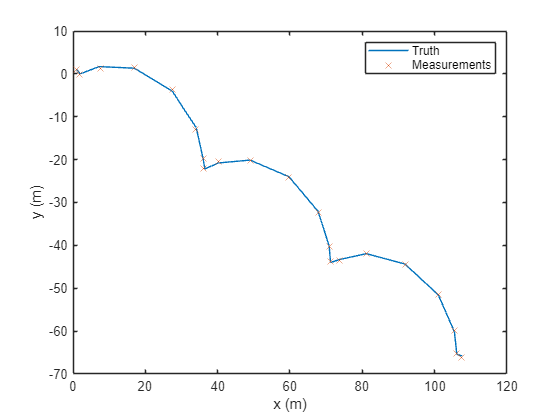

figure
plot(trueStates(1,:),trueStates(3,:),"DisplayName","Truth")
hold on
plot(measurements(1,:),measurements(2,:),"x","DisplayName","Measurements")
xlabel("x (m)")
ylabel("y (m)")
legend

Create a `trackingKF` filter with a custom motion model. Enable the control input by specifying the control model. Specify the initial state in the filter based on the first measurement.

initialFilterState = [measurements(1,1); 0; measurements(2,1); 0];
filter = trackingKF("MotionModel","Custom", ...
    "StateTransitionModel",A, ...
    "MeasurementModel",H, ...
    "ControlModel",B, ...
    "State",initialFilterState);

Estimate states by using the `predict` and `correct` object functions.

estimateStates = NaN(4,steps);
estimateStates(:,1) = initialFilterState;
for i = 2:steps
    predict(filter,U(:,i-1));
    estimateStates(:,i) = correct(filter,measurements(:,i));
end

Visualize the state estimates.

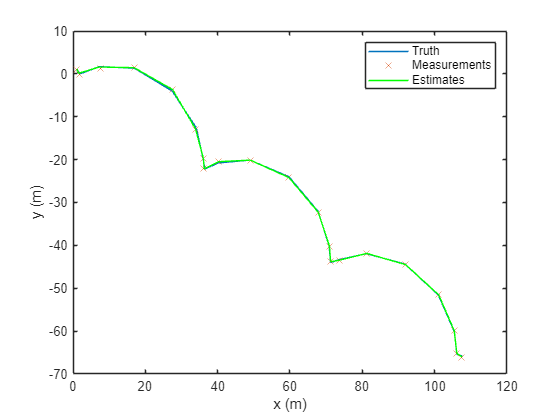

plot(estimateStates(1,:),estimateStates(3,:),"g","DisplayName","Estimates");

*Copyright 2021 The MathWorks, Inc.*